# **demo17 of Im2mesh package**

demo17 - Refine mesh

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB, you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function bounds2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Overview

Please take a look at demo14 or demo15 before starting demo17.

There are several methods to refine mesh:

- Refine mesh by splitting all elements (example 1)

- Specify mesh size at a point (example 2)

- Specify mesh size in an area (example 3-6)

- Add interior constraint edges (example 7)

- Refine mesh near boundary (example 8)

We will demostrate method 1 to 5 in demo17.

Note that demo17 only works for MESH2D. If you use Gmsh as mesh generator, please refer to the following video on how to refine mesh locally: [https://www.youtube.com/watch?v=GL6GUoIwSdU](https://www.youtube.com/watch?v=GL6GUoIwSdU)

## Function bounds2mesh

We will achieve method 1 to 5 via parameter settings of function bounds2mesh.

Function bounds2mesh has 4 input arguments. The last input argument 'opt' is optional.

- **opt** - a structure array. It is the options for bounds2mesh. It stores extra parameter settings for bounds2mesh.

- **opt.mesh_kind** - Method used to create mesh-size functions based on an estimate of the "local-feature-size". Value: 'delaunay' or 'delfront'. Default value: 'delaunay'

- **opt.tf_smooth** - Boolean. Value: 0 or 1. Whether improve triangulation quality by adjusting the vertex positions and mesh topology. Default value: 1

- **opt.num_split** - Number of splitting for refining mesh. Each triangle is split into four new sub-triangles. Default value: 0

- **opt.bound_size** - Element size at constraint edges (i.e., polygonal boundary). This is used to refine mesh near all polygonal boundary, which maybe useful in some cases. If you don t need to refine mesh near boundary, you can set bound_size to 0. Default value: 0

- **opt.local_max **- n-by-2 array, used to specify max mesh size in a part. '[2, 0.5; 3, 0.15]' means that max mesh size in part 2 is 0.5; max mesh size in part 3 is 0.15. When set as [], this parameter will be ignored. Default value: []

- **opt.pnt_size** - p-by-3 array, used to specify mesh size at a point. Each row is a point and its corresponding mesh size. '[2, 3, 0.4; 5, 1, 0.15]' means that mesh size at point (2, 3) is 0.4; mesh size at point (5, 1) is 0.15. Default value: []

- **opt.interior_poly** - c-by-1 cell array, used to specify interior edge constraints. opt.interior_poly{i} is a n-by-2 array, for x and y coordinates of a 2d polyline. Experimental feature. May fail in some cases. Default value: {}

- **opt.disp** - Verbosity. Set as 'inf' to mute verbosity. Default value: 10

We will use 'opt.num_split' to refine mesh by splitting all elements.

We will use 'opt.pnt_size' to specify mesh size at a point.

We will use 'opt.local_max' to specify mesh size in an area.

We will use 'opt.interior_poly' to add interior constraint edges.

We will use 'opt.bound_size' to refine mesh near all boundaries.

## Example 1. Refine mesh by splitting all elements

We will do this by setting 'opt.num_split'.

Create polyshape

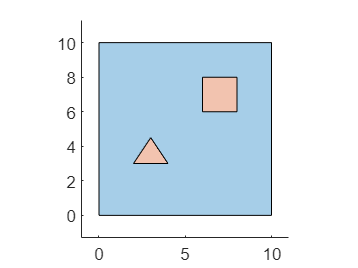

% create polyshape
vert1 = 10 * [ 0 0; 1 0; 1 1; 0 1 ];
ps1 = polyshape(vert1);

vert2 = [2 3] + [0 0; 2 0; 1 1.5];
ps2 = polyshape(vert2);

vert3 = [6 6] + 2*[ 0 0; 1 0; 1 1; 0 1 ];
ps3 = polyshape(vert3);

psB = union( ps2, ps3 );
psA = subtract( ps1, psB );
psCell = { psA; psB };

% plot psCell
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

We saw that there are 2 parts (or 2 phases): psCell{1} and psCell{2}

% save psCell for later usage
save demo17_data.mat  psCell

### Without splitting

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

Generate mesh

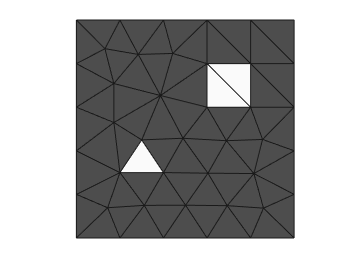

hmax = 2; 
grad_limit = 0.25;

opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Refine by splitting (once)

We can split all elements by setting 'opt.num_split = 1;'

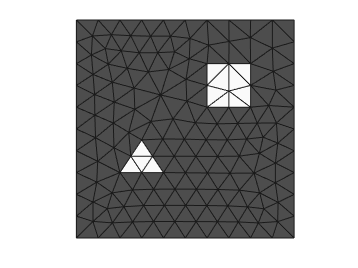

opt = [];
opt.disp = inf;     % silence verbosity
opt.num_split = 1;  % refine mesh by splitting elements

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Refine by splitting (twice)

We can split all elements further by setting 'opt.num_split = 2;'

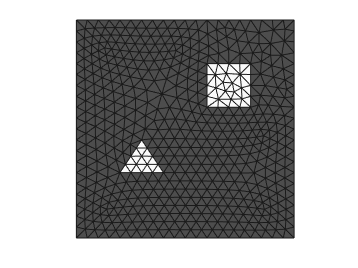

opt = [];
opt.disp = inf;     % silence verbosity
opt.num_split = 2;  % refine mesh by splitting elements

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

clearvars

## Example 2. Specify mesh size at a point

We will do this by setting 'opt.pnt_size'.

Create polyshape

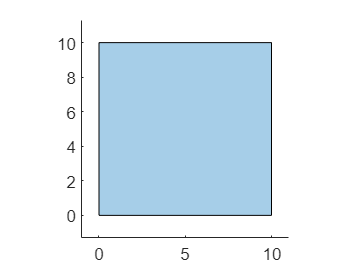

% square
vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);
psCell = {psSq};    % a cell array of polyshape

plot(psSq); axis equal

### Single point

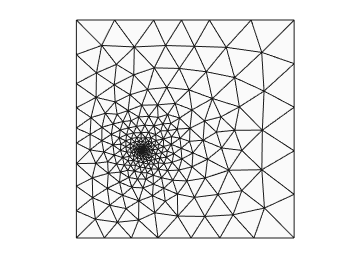

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

hmax = 2; 
grad_limit = 0.25;

opt = [];
opt.disp = inf;     % silence verbosity

pnt = [3, 4];       % 1 point
hsize = 0.05;       % mesh size at point
opt.pnt_size = [ pnt, hsize ];  % p-by-3 array

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Multiple points

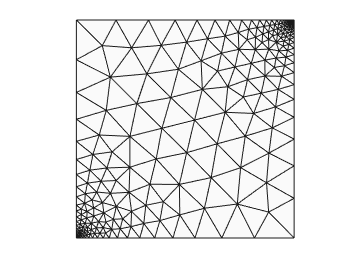

opt = [];
opt.disp = inf;     % silence verbosity

pnt = [0, 0; 10, 10];     % 2 points
hsize = [ 0.05; 0.02 ];   % mesh size at point
opt.pnt_size = [ pnt, hsize ];  % p-by-3 array

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Attraction issue

When points are close, they will attract each other.

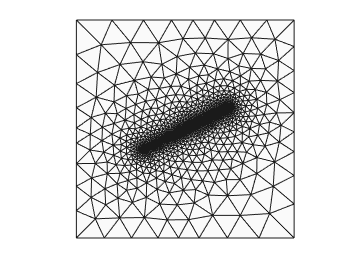

opt = [];
opt.disp = inf;     % silence verbosity

pnt = [3, 4; 7, 6];       % 2 points
hsize = [ 0.05; 0.02 ];   % mesh size at point
opt.pnt_size = [ pnt, hsize ];  % p-by-3 array

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

There are two approaches to fix this issue.

Approach 1 specify mesh size at dummy point via 'opt.pnt_size'.

Approach 2 specify initial mesh size via 'opt.hinitial'.

### Fix attraction - approach 1

We can fix this issue by adding dummy point between them. Here, point (5,5) is the dummy point.

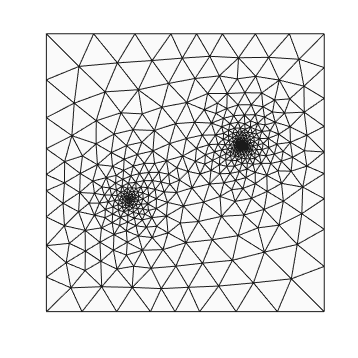

opt = [];
opt.disp = inf;     % silence verbosity

pnt = [3, 4; 7, 6; 5, 5];    % 3 points
hsize = [ 0.05; 0.02; 1 ];   % mesh size at point
opt.pnt_size = [ pnt, hsize ];  % p-by-3 array

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

Awesome!

### Fix attraction - approach 2

We can fix this issue by specifying initial mesh size via 'opt.hinitial'.

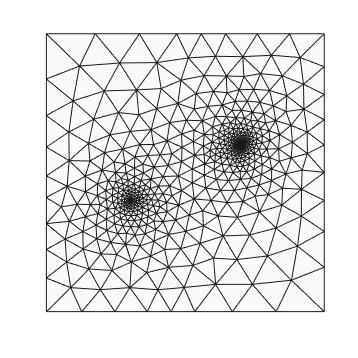

opt = [];
opt.disp = inf;     % silence verbosity

pnt = [3, 4; 7, 6];       % 2 points
hsize = [ 0.05; 0.02 ];   % mesh size at point
opt.pnt_size = [ pnt, hsize ];  % p-by-3 array

opt.hinitial = 2;   % initial mesh size

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

clearvars

## Example 3. Refine mesh in parts

We will do this by setting 'opt.local_max'

Load data (psCell)

load demo17_data.mat

Create pristine mesh for comparision.

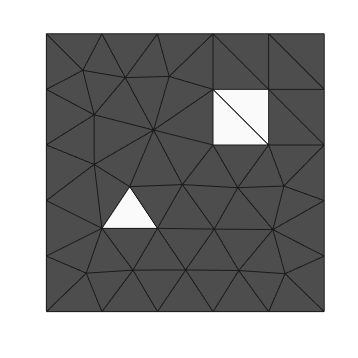

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

hmax = 2; 
grad_limit = 0.25;

opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Max mesh size = 0.5

Suppose we want to refine the mesh in part 2 (or phase 2).

'opt.local_max = [2, 0.5];' means that the maximum mesh size in part 2 is 0.5.

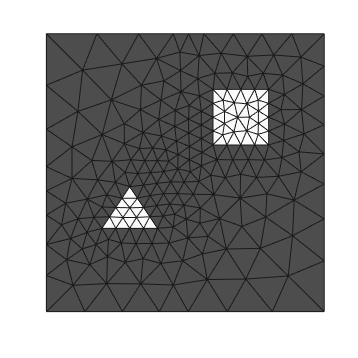

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [2, 0.5];

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Max mesh size = 0.25

We can further refine.

'opt.local_max = [2, 0.25];' means that the maximum mesh size in part 2 is 0.25.

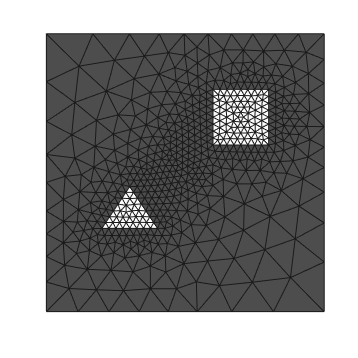

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [2, 0.25];

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Fix

We notice that the mesh between the small square and the triangle also become denser, which might not be what we want.

As I mentioned in example 2, we can fix this issue by adding dummy point or by specifying initial mesh size.

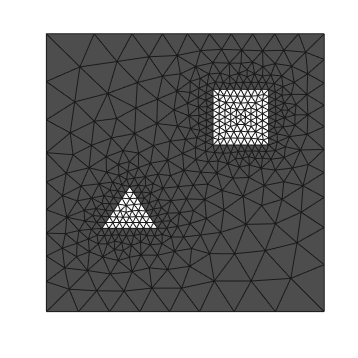

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [2, 0.25];

opt.hinitial = 2;   % initial mesh size

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

clearvars

## Example 4. Refine mesh locally

We will do this by setting 'opt.local_max'

Create polyshape

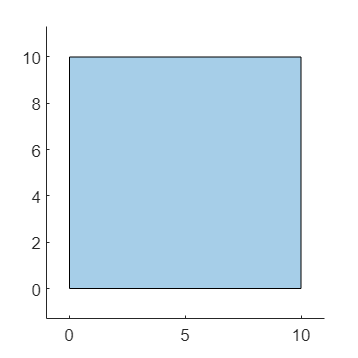

% square
vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);
psCell = {psSq};    % a cell array of polyshape

plot(psSq); axis equal

Generate mesh

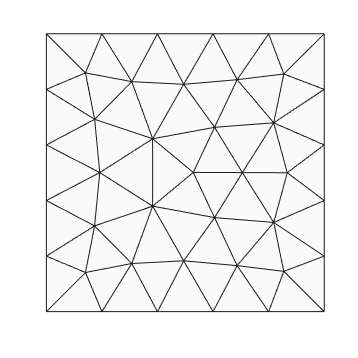

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

hmax = 2; 
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Region of interest

Suppose we want to refine the mesh in the upper right corner of the square.

Let's locate the region of interest (ROI) using polyshape. 

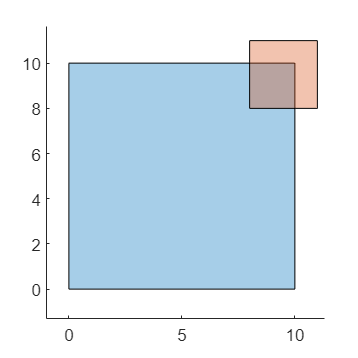

vertex = [8, 8] + 3*[ 0 0; 1 0; 1 1; 0 1 ];
psROI = polyshape(vertex);

figure; axis equal
hold on
for i = 1: length(psCell)
    plot(psCell{i});
end

plot(psROI);
hold off

### Specify as a new part

We use boolean operations to find intersects between psROI and psCell.

We will make intersecting regions become new parts in psCell.

% find intersect
psC_inters = psCell;

for i = 1: length(psCell)
    psC_inters{i} = intersect( psCell{i}, psROI );
end

% delete empty elements in cell array
psC_inters = psC_inters( ~cellfun('isempty', psC_inters) );

% remove overlap
for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psROI );
end

% append psC_inters to the end of psCell
psCell = [ psCell; psC_inters ];

Plot

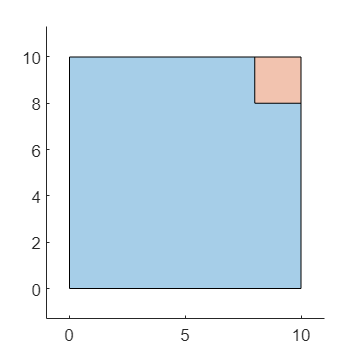

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

Plot one by one

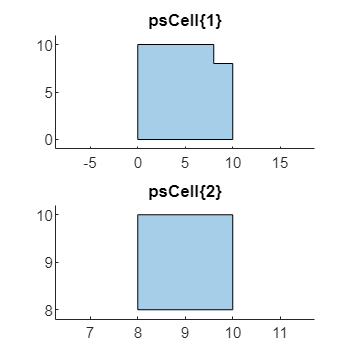

figure
for i = 1: length(psCell)
    subplot(2,1,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

psCell{2} is newly added.

### Generate mesh

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

Create pristine mesh for comparision.

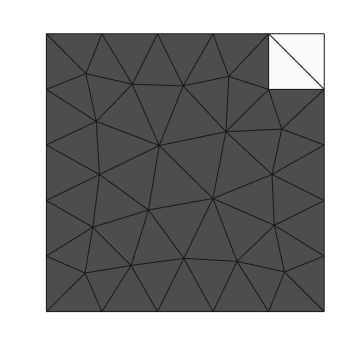

hmax = 2;
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Refine mesh

We can refine the mesh in the upper right corner.

'opt.local_max = [2, 0.3];' means that the maximum mesh size in part 2 is 0.3.

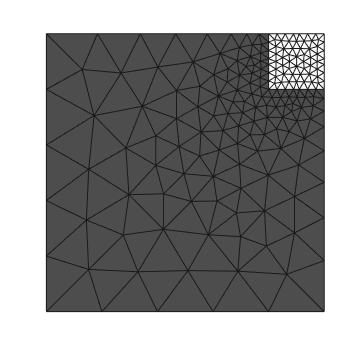

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [2, 0.3];

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

We can re-assign part label (or phase label).

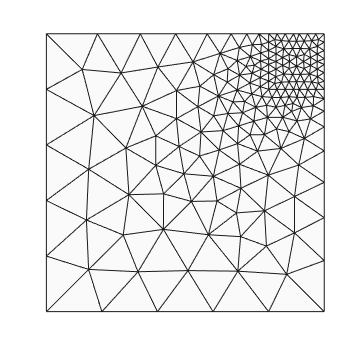

tnum_new = tnum;
tnum_new( tnum == 2) = 1;

plotMeshes(vert,tria,tnum_new);

clearvars

## Example 5. Refine mesh locally

We will do this by setting 'opt.local_max'

Load image

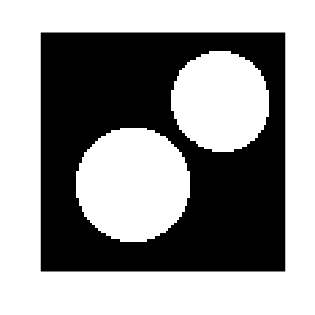

im = imread('Circle2.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Convert image to polygonal boundary

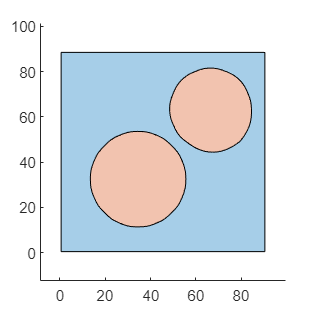

opt = [];   % reset opt
opt.tolerance = 0.05;
opt.tf_mesh = false;
bounds = im2mesh( im, opt );
psCell = bound2polyshape(bounds);

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

### Region of interest

Suppose we want to refine the mesh in the middle. 

Let's locate the region of interest (ROI) using polyshape. 

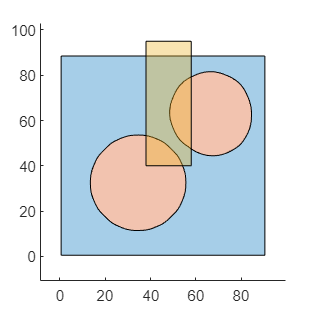

vertex = [38, 95; 58, 95; 58, 40; 38 40 ];
psROI = polyshape(vertex);

figure; axis equal
hold on
for i = 1: length(psCell)
    plot(psCell{i});
end

plot(psROI);
hold off

### Specify as new parts

We use boolean operations to find intersects between psROI and psCell.

We will make intersecting regions become new parts in psCell.

% find intersect
psC_inters = psCell;

for i = 1: length(psCell)
    psC_inters{i} = intersect( psCell{i}, psROI );
end

% delete empty elements in cell array
psC_inters = psC_inters( ~cellfun('isempty', psC_inters) );

% remove overlap
for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psROI );
end

% append psC_inters to the end of psCell
psCell = [ psCell; psC_inters ];

Plot

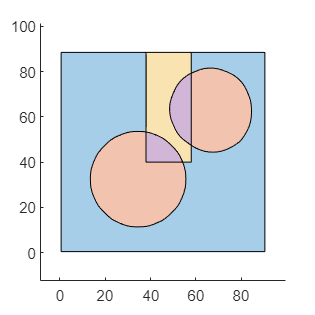

figure; axis equal
hold on
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

Plot one by one

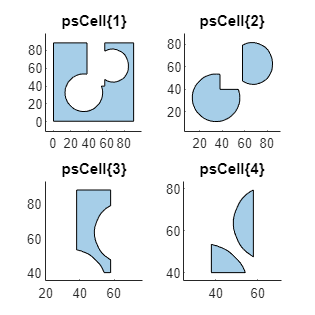

figure
for i = 1: length(psCell)
    subplot(2,2,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

psCell{3} and psCell{4} are newly added.

### Generate mesh

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

bounds = getCtrlPnts( bounds, false );
tolerance = 0.06;
bounds = simplifyBounds( bounds, tolerance );

Create pristine mesh for comparision.

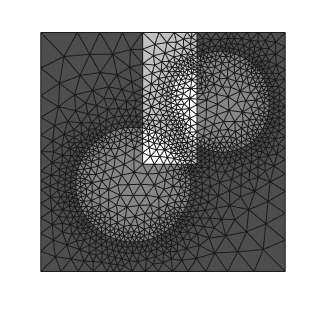

hmax = 500;
grad_limit = 0.25;

opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

Zoom in

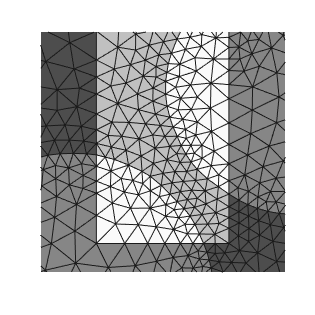

plotMeshes(vert,tria,tnum);

xlim([29.6 66.5])
ylim([35.7 71.9])

### Refine mesh

We can refine the mesh in the region of interest.

'opt.local_max = [3, 0.8];' means that the maximum mesh size in part 3 is 0.8.

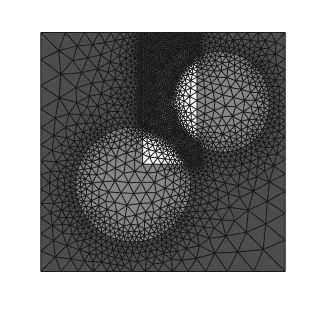

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [3, 0.8];

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

Zoom in

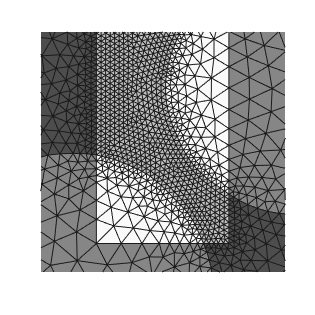

plotMeshes(vert,tria,tnum);

xlim([29.6 66.5])
ylim([35.7 71.9])

We can re-assign part label.

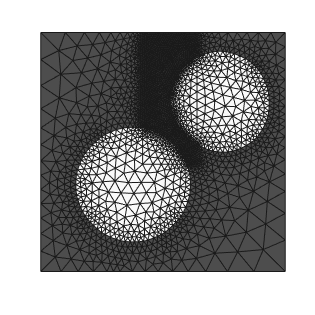

tnum_new = tnum;
tnum_new(tnum == 4) = 2;
tnum_new(tnum == 3) = 1;
plotMeshes(vert,tria,tnum_new);

Zoom in

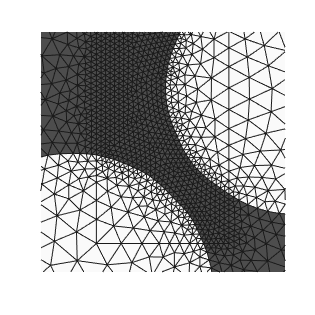

plotMeshes(vert,tria,tnum_new);

xlim([29.6 66.5])
ylim([35.7 71.9])

Awesome!

clearvars

## Example 6. Refine mesh in a region of a part

What if we want to refine a specific region in a part?

Load data (psCell)

load demo17_data.mat

We will have to specify the interested region as a new part.

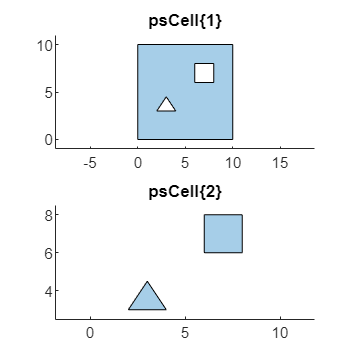

figure
for i = 1: length(psCell)
    subplot(2,1,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

We saw that part 2 - psCell{2} has two regions: square and triangles.

Suppose we want to refine mesh in the square region of part 2.

### Extract region

We can use matlab built-in function regions to extract region from polyshape.

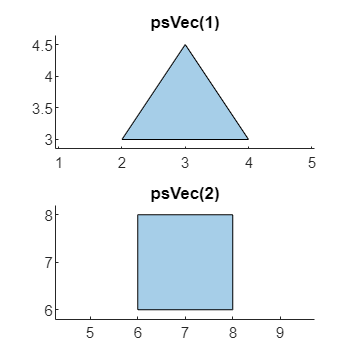

% psVec is a vector of polyshape
psVec = regions( psCell{2} ); 

figure
for i = 1: length(psVec)
    subplot(2,1,i);
    plot( psVec(i) );  axis equal;
    title(['psVec(' num2str(i), ')']);
end

psVec(2) is the square we interested in.

### Specify as a new part

We use boolean operations to make psVec(2) become a new part in psCell

psNew = psVec(2);

% remove overlap
for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psNew );
end

% add to the end of psCell
psCell{end+1} = psNew;

Plot

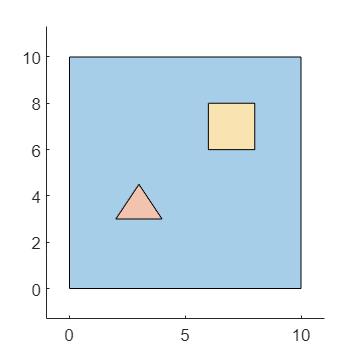

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

Plot one by one

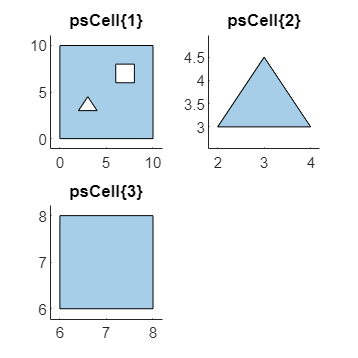

figure
for i = 1: length(psCell)
    subplot(2,2,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

The square we interested in is now part 3 (psCell{3})

### Refine mesh in part 3

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

Generate mesh.

'opt.local_max = [3, 0.25];' means that the max mesh size in part 3 is 0.25.

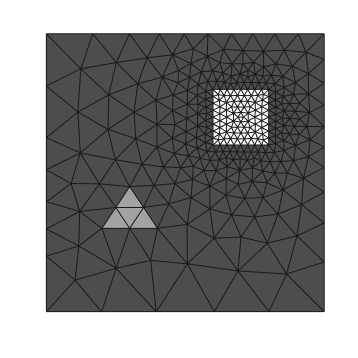

hmax = 2; 
grad_limit = 0.25;

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [3, 0.25];

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Refine in multiple parts

'opt.local_max = [2, 0.15; 3, 0.25];' means that the max mesh size in part 2 is 0.15; the max mesh size in part 3 is 0.25.

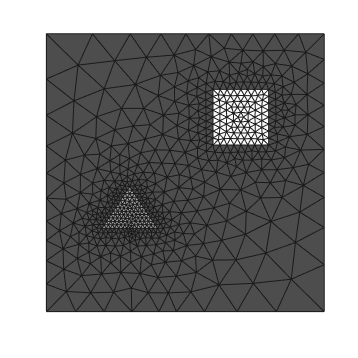

opt = [];
opt.disp = inf;     % silence verbosity
opt.local_max = [2, 0.15; 3, 0.25];

opt.hinitial = 2;   % set initial mesh size to fix attraction

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

clearvars

## Example 7. Add interior constraint edges

We will do this by setting 'opt.interior_poly'

Create a square

% square
vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);
psCell = {psSq};    % a cell array of polyshape

Create pristine mesh for comparision.

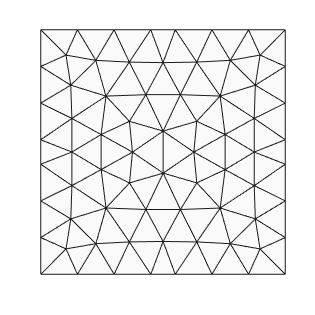

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

hmax = 1.5; 
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Define interior constraint edges

Use 2d polyline to define interior constraint edges

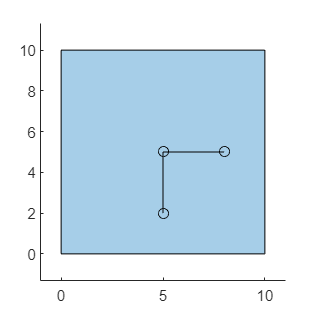

% 2d polyline
poly1 = [5, 2; 5, 5; 8, 5];

% plot psCell and polyline
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end

plot( poly1(:,1), poly1(:,2), 'ko-' ); 
hold off

### Generate mesh with interior constraints

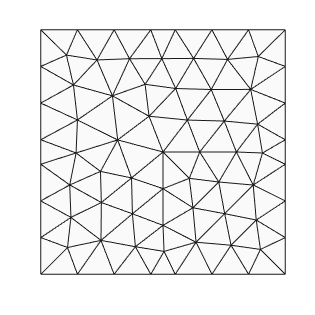

opt = [];
opt.disp = inf;     % silence verbosity

opt.interior_poly{1} = poly1;

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

We saw the mesh is conform to the interior constraint edges.

### Refine mesh

We can use function insertEleSizeSeed to add mesh seed to the polyline. This will refine the mesh near interior constraint edges.

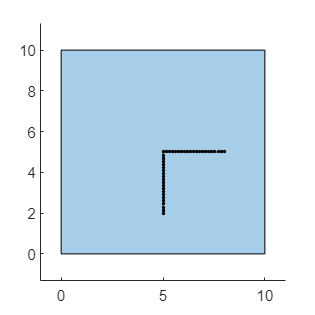

% 2d polyline
poly1 = [5, 2; 5, 5; 8, 5];
target_size = 0.15;
poly1 = insertEleSizeSeed( poly1, target_size );

% plot psCell and polyline
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end

plot( poly1(:,1), poly1(:,2), 'k.-' ); 
hold off

Generate mesh

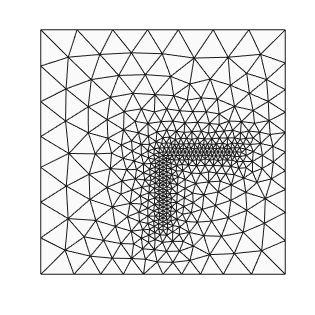

opt = [];
opt.disp = inf;     % silence verbosity
opt.interior_poly{1} = poly1;

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Multiple polyline

'opt.interior_poly' also works for multiple polylines.

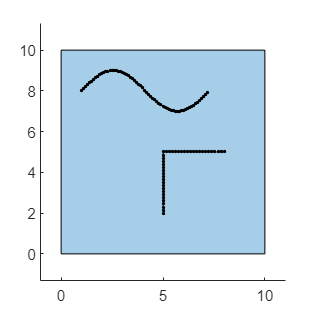

% 2d polyline (for sine curve)
t = 0:0.1:2*pi;
x = t;
y = 8 + sin(x);
poly2 = [1+x', y'];

% plot psCell and polyline
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end

plot( poly1(:,1), poly1(:,2), 'k.-' ); 
plot( poly2(:,1), poly2(:,2), 'k.-' ); 
hold off

Generate mesh

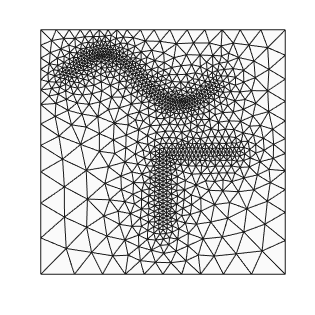

opt = [];
opt.disp = inf;     % silence verbosity

opt.interior_poly{1} = poly1;
opt.interior_poly{2} = poly2;

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

Awesome!

clearvars

## Example 8. Refine mesh near boundary

We will do this by setting 'opt.bound_size'

Load data (psCell)

load demo17_data.mat

Create pristine mesh for comparision.

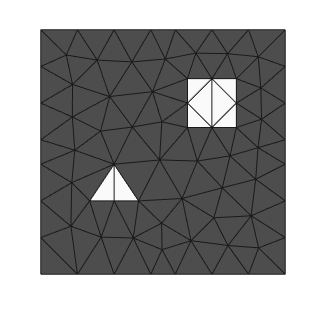

bounds = polyshape2bound(psCell);
tol_intersect = 1e-6;
bounds = addIntersectPnts( bounds, tol_intersect );

hmax = 1.5; 
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

### Refine mesh

We will use 'opt.bound_size' to add uniform mesh seeds to all boundaries. This will refine the mesh near all boundaries.

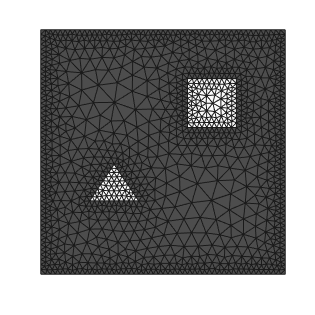

opt = [];
opt.disp = inf;     % silence verbosity

opt.bound_size = 0.2;  % space between seeds

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit, opt );
plotMeshes(vert,tria,tnum);

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo